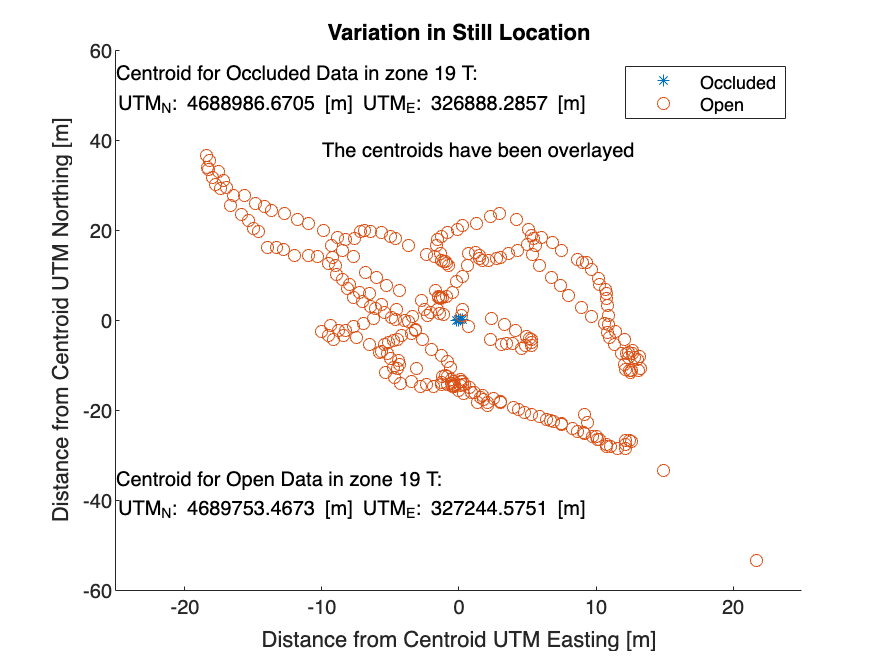

clear all
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
file_namewalk_op = 'bag_walking.bag';
file_pathwalk_op = fullfile('/Users','jakobringberg','Desktop','LINUX_SHARING','MY_BAG_FILES',file_namewalk_op);

file_namewalk_oc = 'bag_walking_occluded.bag';
file_pathwalk_oc = fullfile('/Users','jakobringberg','Desktop','LINUX_SHARING','MY_BAG_FILES',file_namewalk_oc);

file_nameop = 'bag_still_open.bag';
file_pathop = fullfile('/Users','jakobringberg','Desktop','LINUX_SHARING','MY_BAG_FILES',file_nameop);

file_nameoc = 'bag_still.bag';
file_pathoc = fullfile('/Users','jakobringberg','Desktop','LINUX_SHARING','MY_BAG_FILES',file_nameoc);

bag_walk_op = rosbag(file_pathwalk_op);
bag_walk_oc = rosbag(file_pathwalk_oc);
bag_op = rosbag(file_pathop);
bag_oc = rosbag(file_pathoc);

bSel_walk_op = select(bag_walk_op,'Topic','/wire');
bSel_walk_oc = select(bag_walk_oc,'Topic','/wire');
bSel_op = select(bag_op,'Topic','/wire');
bSel_oc = select(bag_oc,'Topic','/wire');

msgStructs_walk_op = readMessages(bSel_walk_op,'DataFormat','struct');
msgStructs_walk_op{1};

msgStructs_walk_oc = readMessages(bSel_walk_oc,'DataFormat','struct');
msgStructs_walk_oc{1};

msgStructs_op = readMessages(bSel_op,'DataFormat','struct');
msgStructs_op{1};

msgStructs_oc = readMessages(bSel_oc,'DataFormat','struct');
msgStructs_oc{1};

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
Time_walk_oc = cellfun(@(m) double(m.Header.Stamp.Sec),msgStructs_walk_oc);
NorthingPoints_walk_oc = cellfun(@(m) double(m.UtmNorthing),msgStructs_walk_oc);
EastingPoints_walk_oc = cellfun(@(m) double(m.UtmEasting),msgStructs_walk_oc);
avg_north_walk_oc = mean(NorthingPoints_walk_oc);
avg_east_walk_oc = mean(EastingPoints_walk_oc);

NorthingPoints_walk_oc_dev = NorthingPoints_walk_oc-avg_north_walk_oc;
EastingPoints_walk_oc_dev = EastingPoints_walk_oc-avg_east_walk_oc;

Alt_walk_oc = cellfun(@(m) double(m.Alt),msgStructs_walk_oc);
%%%%%%%%%%%%%%%%%%%%%%

Time_walk_op = cellfun(@(m) double(m.Header.Stamp.Sec),msgStructs_walk_op);
NorthingPoints_walk_op = cellfun(@(m) double(m.UtmNorthing),msgStructs_walk_op);
EastingPoints_walk_op = cellfun(@(m) double(m.UtmEasting),msgStructs_walk_op);
avg_north_walk_op = mean(NorthingPoints_walk_op);
avg_east_walk_op = mean(EastingPoints_walk_op);

NorthingPoints_walk_op_dev = NorthingPoints_walk_op-avg_north_walk_op;
EastingPoints_walk_op_dev = EastingPoints_walk_op-avg_east_walk_op;

Alt_walk_op = cellfun(@(m) double(m.Alt),msgStructs_walk_op);
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
Time_op = cellfun(@(m) double(m.Header.Stamp.Sec),msgStructs_op);
NorthingPoints_op = cellfun(@(m) double(m.UtmNorthing),msgStructs_op);
EastingPoints_op = cellfun(@(m) double(m.UtmEasting),msgStructs_op);
avg_north_op = mean(NorthingPoints_op);
avg_east_op = mean(EastingPoints_op);
centroid_op = ([avg_north_op,avg_east_op]);

NorthingPoints_op_dev = NorthingPoints_op-avg_north_op;
EastingPoints_op_dev = EastingPoints_op-avg_east_op;

Alt_op = cellfun(@(m) double(m.Alt),msgStructs_op);

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
Time_oc = cellfun(@(m) double(m.Header.Stamp.Sec),msgStructs_oc);
NorthingPoints_oc = cellfun(@(m) double(m.UtmNorthing),msgStructs_oc);
EastingPoints_oc = cellfun(@(m) double(m.UtmEasting),msgStructs_oc);
avg_north_oc = mean(NorthingPoints_oc);
avg_east_oc = mean(EastingPoints_oc);
centroid_oc = ([avg_north_oc,avg_east_oc]);

NorthingPoints_oc_dev = NorthingPoints_oc-avg_north_oc;
EastingPoints_oc_dev = EastingPoints_oc-avg_east_oc;

Alt_oc = cellfun(@(m) double(m.Alt),msgStructs_oc);
%%%%%%%%%%%%%%%%%%%%%%%%%%%

figure(1)

scatter(EastingPoints_op_dev,NorthingPoints_op_dev,"Marker","*")
hold on
scatter(EastingPoints_oc_dev,NorthingPoints_oc_dev,"Marker","o")
hold off
axis([-25 25 -60 60])
title('Variation in Still Location')
xlabel('Distance from Centroid UTM Easting [m]')
ylabel('Distance from Centroid UTM Northing [m]')
legend({'Occluded','Open'},'Location','northeast')

txt = {'Centroid for Occluded Data in zone 19 T:'};
text(-25,55,txt)
txt = ['UTM_N: ' num2str(centroid_oc(1)) ' [m]' ' UTM_E: ' num2str(centroid_oc(2)) ' [m]'];
text(-25,48,txt)

txt = {'Centroid for Open Data in zone 19 T:'};
text(-25,-35,txt)
txt = ['UTM_N: ' num2str(centroid_op(1)) ' [m]' ' UTM_E: ' num2str(centroid_op(2)) ' [m]'];
text(-25,-42,txt)


txt = {'The centroids have been overlayed'};
text(-10,38,txt)

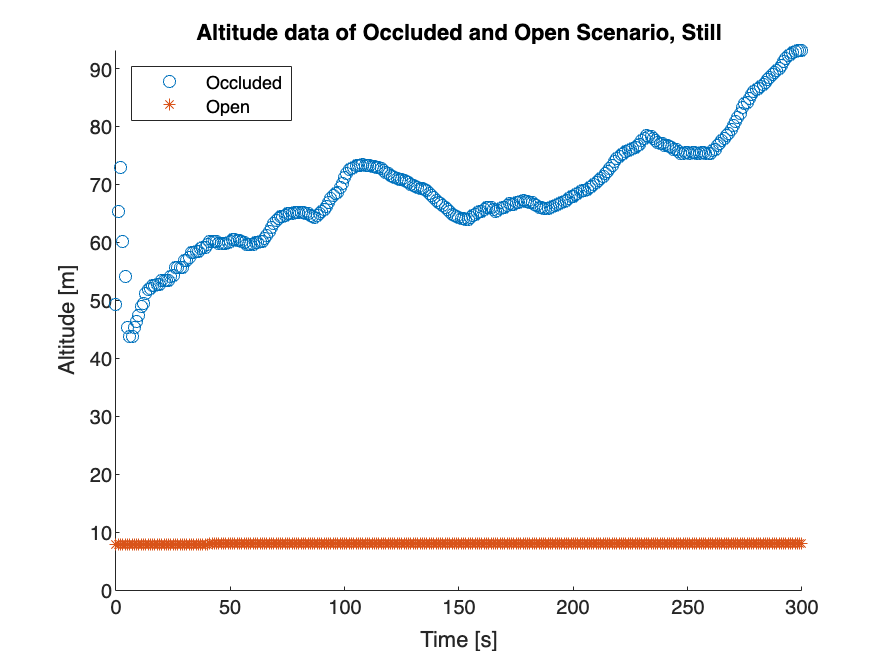


%hold on
%plot(centroid_op,"LineWidth",4)
%hold on
%plot(centroid_oc,"LineWidth",4)

%%%%%%%%%%%%%%%%



%%%%%%%%%%%%%%%%%%%%

figure(2)

Time_oc1 = Time_oc-Time_oc(1);
scatter(Time_oc1,Alt_oc,"Marker","o")
hold on
Time_op1 = Time_op-Time_oc(1)-4193;
scatter(Time_op1,Alt_op,"Marker","*")
axis([0 300 0 inf])
title('Altitude data of Occluded and Open Scenario, Still')
xlabel('Time [s]')
ylabel('Altitude [m]')
legend({'Occluded','Open'},'Location','northwest')
hold off

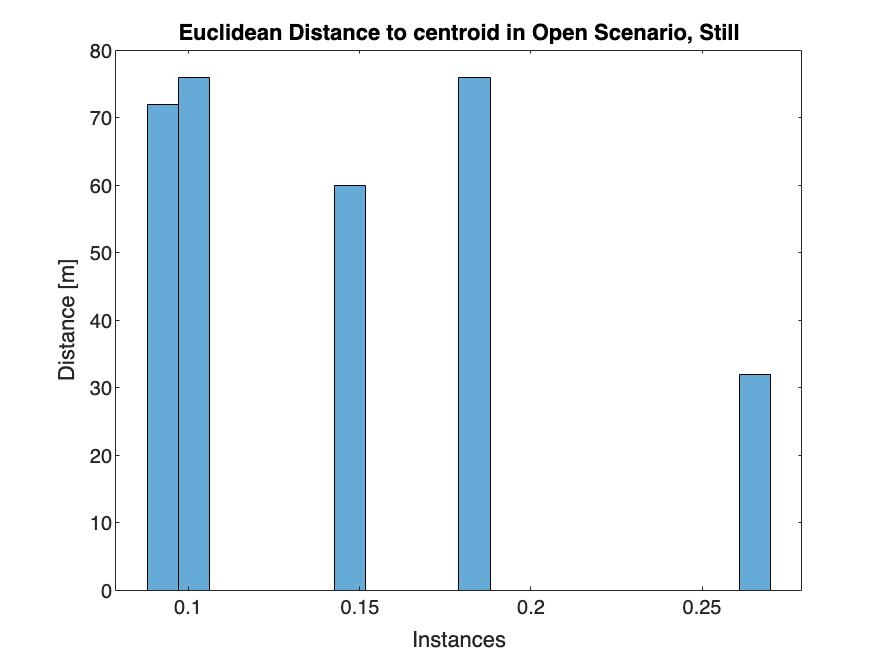



%%%%%%%%%%%%%%%%%%%%

figure(3)
 
EC_open = sqrt(NorthingPoints_op_dev.^2+EastingPoints_op_dev.^2);
histogram(EC_open,20);
title('Euclidean Distance to centroid in Open Scenario, Still')
xlabel('Instances')
ylabel('Distance [m]')

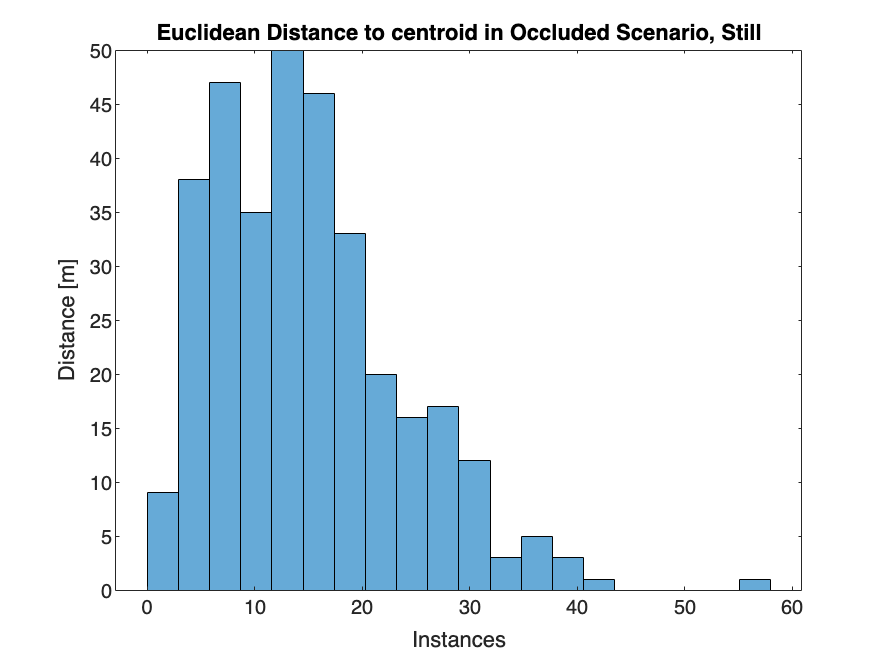


figure(4)

EC_occluded = sqrt(NorthingPoints_oc_dev.^2+EastingPoints_oc_dev.^2); 
histogram(EC_occluded,20);
title('Euclidean Distance to centroid in Occluded Scenario, Still')
xlabel('Instances')
ylabel('Distance [m]')

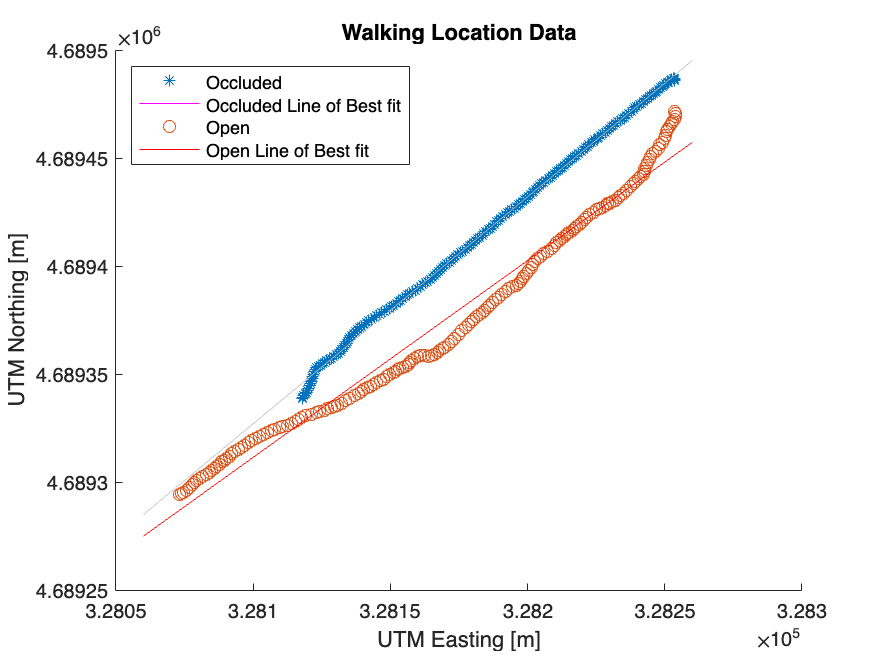


%%%%%%%%%%%%%%%%%%%%%%%%

figure(5)

EastingPoints_walk_op1 = EastingPoints_walk_op+946.75857;
NorthingPoints_walk_op1 = NorthingPoints_walk_op-280.24475;
LBF_op = polyfit(EastingPoints_walk_op1,NorthingPoints_walk_op1,1);
LBF_oc = polyfit(EastingPoints_walk_oc,NorthingPoints_walk_oc,1);
scatter(EastingPoints_walk_op1,NorthingPoints_walk_op1,"Marker","*")
l1 = lsline;
set(l1(1),'color','magenta')
hold on
%plot(polyval(EastingPoints_walk_op1,LBF_op))
hold on
scatter(EastingPoints_walk_oc,NorthingPoints_walk_oc,"Marker","o")
l2 = lsline;
set(l2(1),'color','red')
hold on
%plot(polyval(EastingPoints_walk_oc,LBF_oc))
title('Walking Location Data')
xlabel('UTM Easting [m]')
ylabel('UTM Northing [m]')
legend({'Occluded','Occluded Line of Best fit','Open','Open Line of Best fit'},'Location','northwest')
hold off

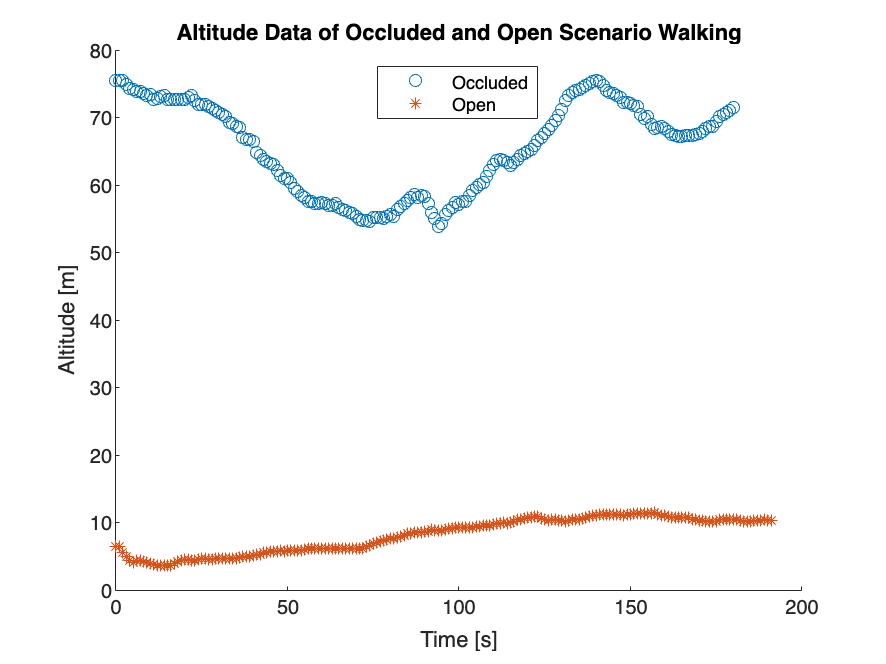


%%%%%%%%%%%%%%%%%%
figure(6)

Time_walk_oc1 = Time_walk_oc-Time_walk_oc(1);
scatter(Time_walk_oc1,Alt_walk_oc,"Marker","o")
hold on
Time_walk_op1 = Time_walk_op+193189-Time_walk_oc(1);
scatter(Time_walk_op1,Alt_walk_op,"Marker","*")
title('Altitude Data of Occluded and Open Scenario Walking')
xlabel('Time [s]')
ylabel('Altitude [m]')
legend({'Occluded','Open'},'Location','north')
hold off